# Presas y depredadores 

Consideremos la peninsula ibérica en la que hay linces (depredadores) y conejo (presas). Los linces matan a sus presas, es decir, a los conejos, para alimentarse. Sean L y C las poblaciones respectivas en un instante de tiempo t, se pide formular el modelo continuo para examinar el comportamiento a largo plazo de las dos especies bajo unos pocos supuestos: 

-  Los conejos son la única fuente de alimento para los linces y los linces son los únicos depredadores de los conejos. 

- La población de conejos crecerá si no hay linces y, sin la población de conejos, los linces se extinguirán. 

- El ritmo de crecimiento de la población de linces aumenta con la presencia de la población de conejos y el ritmo de crecimiento de la población de conejos disminuye con la presencia de la población de linces. 

Decimos que $\alpha$ es la tasa a la que los linces mueren si no hay conejos disponibles para alimentarse y $\beta \;$es la tasa de crecimiento de esta misma especie cuando el alimento está disponible. Del mismo modo la tasa de conejos crece a una tasa $\gamma$ y dismiuyen a una tasa $\delta$ en presencia de población de linces. Suponiendo que el número actual de linces y conejos es de 500 animales de cada especie, calcular el punto de equilibrio del sistema teniendo en cuenta las siguientes tasas:

                                                                         
$$\begin{array}{l}
\alpha =0\ldotp 5\;\\
\beta =0\ldotp 4\\
\gamma =0\ldotp 1\\
\delta =0\ldotp 17
\end{array}$$


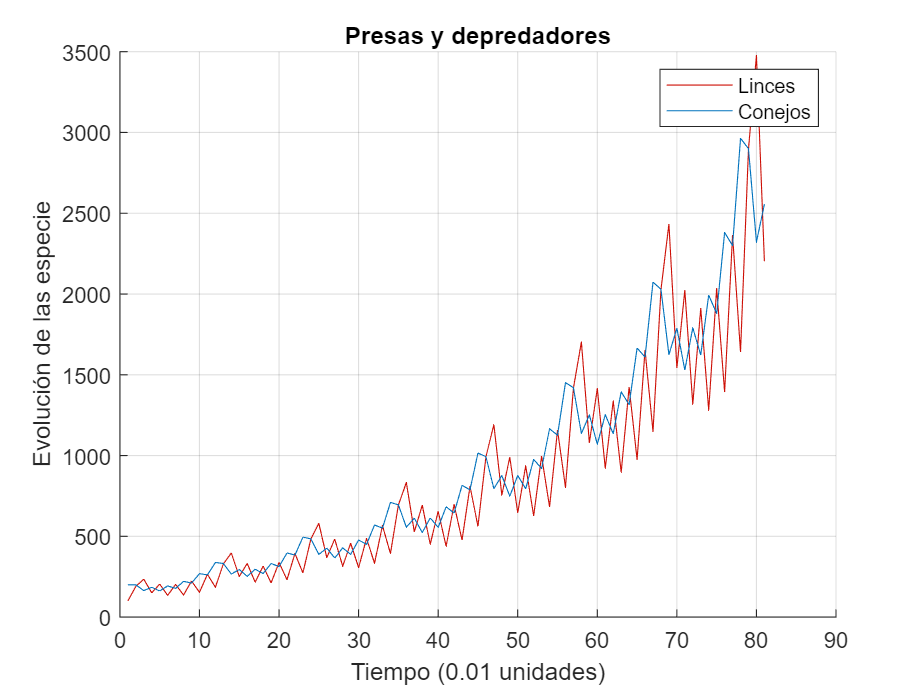

clc, clf, clear

% Defino las cantidades iniciales
L = [100];
C = [200];

% Defino el paso de tiempo dt
t = 0;
dt = 0.01;

% Defino las tasas
alpha = 0.5; % tasa a la que los linces mueren si no hay conejos.
beta = 0.4;  % tasa de crecimiento de los linces cuando hay conejos.

delta = 0.4; % tasa a la que los conejos mueren si hay linces.
gamma = 0.5; % tasa de crecimiento de los conejos.

alpha = L(end) / C(end);


% Calculo la simulación para 2 unidades de tiempo.
while t < 0.8

     t = t + dt;
    
    if L(end) >= C(end)
        beta = 0.2;
        gamma = 0.7;
    else
        beta = 0.7;
        gamma = 0.2;
    end

     % Linces = Nº de linces - alpha * Nº de linces + beta * Nº de conejos. 
     auxL = L(end) - alpha*L(end) + beta*C(end);

     % Conejos = Nº de conejos + gamma * Nº de conejos - delta * Nº de linces.
     auxC = C(end) + gamma*C(end) - delta*L(end);
     
     L = [L auxL];
     C = [C auxC];

end

hold on

plot(L,'Color', '#CD0F06')
xlabel("Tiempo (0.01 unidades)")
ylabel("Evolución de las especie")
title("Presas y depredadores")

plot(C,'Color', '#0072BD')
legend('Linces','Conejos' )
grid on
hold off